clc; clear; close all;

ps_path = 'ps_data';
fileStruct =dir(fullfile(ps_path, '*.csv'));

numFiles = length(fileStruct);
allData = cell(1, numFiles);



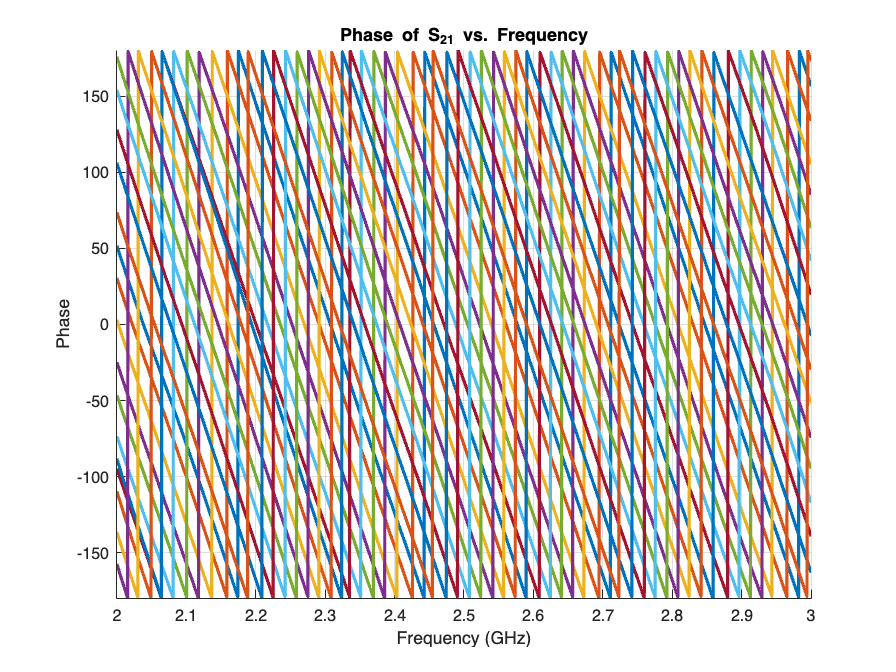


figure; 
hold on;

gifFile = 'PSPlot.gif';

for i = 1:numFiles
    filePath = fullfile(ps_path, fileStruct(i).name);
    data = readmatrix(filePath);
    allData{i} = data;
    % Column 1: Frequency in Hz
    % Column 2: Real part of S21
    % Column 3: Imaginary part of S21
    Freq_Hz = data(:, 1);
    Re_S21 = data(:, 2);
    Im_S21 = data(:, 3);
    
    
    S21_complex = Re_S21 + 1j * Im_S21;
    
    
    Phase_rad = angle(S21_complex);
    
    Phase_deg = rad2deg(Phase_rad);
    
    

    plot(Freq_Hz / 1e9, Phase_deg, 'LineWidth', 2); 
    
    title('Phase of S_{21} vs. Frequency');
    xlabel('Frequency (GHz)');
    ylabel('Phase'); 
    grid on;
    drawnow;
    ylim([-180, 180]);
    exportgraphics(gcf, gifFile, 'Append', true);
        
end
hold off;

fprintf('done!');

done!

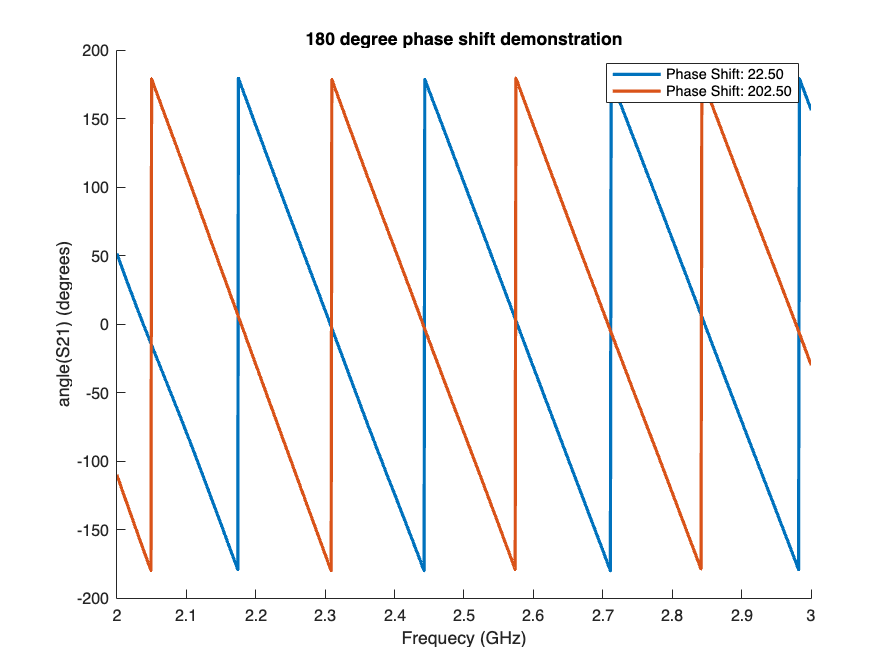

figure();
hold on;

angles = zeros(1001, 2);
idx = 1;

for ii = 1:8:numFiles
    filePath = fullfile(ps_path, fileStruct(ii).name);
    data = readmatrix(filePath);
    allData{ii} = data;
    % Column 1: Frequency in Hz
    % Column 2: Real part of S21
    % Column 3: Imaginary part of S21
    Freq_Hz = data(:, 1);
    Re_S21 = data(:, 2);
    Im_S21 = data(:, 3);

    ang = ii * 360 / 16;

    angleS21 = angle(Re_S21 + 1j * Im_S21) * 180 / pi; % degrees

    angles(:, idx) = angleS21;

    plot(Freq_Hz / 1e9, angleS21, 'LineWidth', 2, 'DisplayName', sprintf('Phase Shift: %.2f', ang));

    idx = idx + 1;
end

hold off;
legend show;
xlabel('Frequecy (GHz)');
ylabel('angle(S21) (degrees)');
title('180 degree phase shift demonstration');

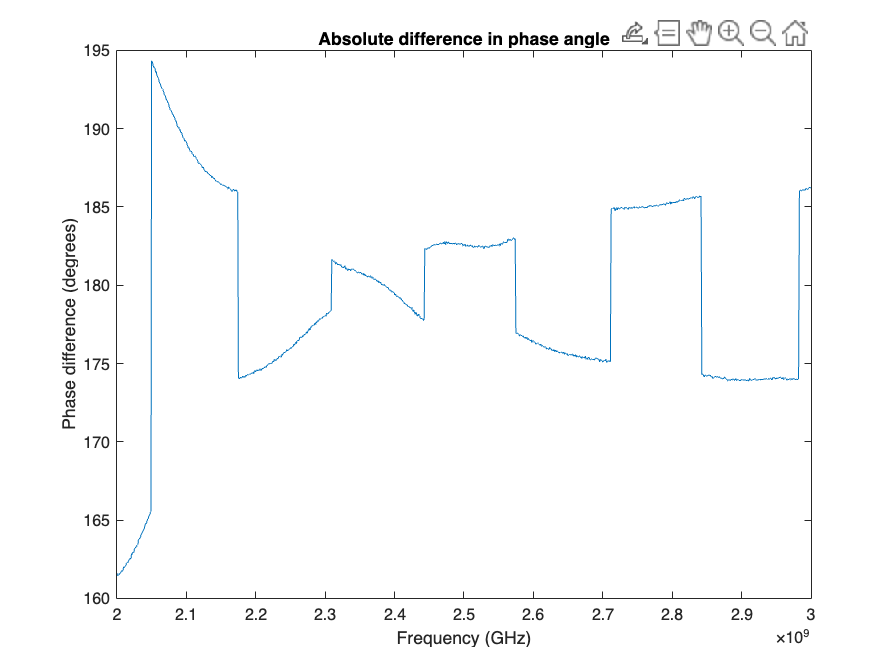

figure();
plot(Freq_Hz, abs(angles(:, 1) - angles(:, 2)));
title('Absolute difference in phase angle')
xlabel('Frequency (GHz)')
ylabel('Phase difference (degrees)')